% move=1;
% params.N_L=5;
% 
% params.cf=1;
% params.numTX=4;
% params.numRX=4;
% params.Ny=4;
% params.snr=20;
% 
% 
% 
% [theta,phi]=plane_move_run_optimized(params,move);
res_phi(n,s,:)-phi'

ans = ans(:,:,1) =

    3.8000
    2.8000
    1.8000
    0.8000
   -0.2000
   -1.2000
   -2.2000
   -3.2000
   -4.2000
   -5.2000


ans(:,:,2) =

    4.8000
    3.8000
    2.8000
    1.8000
    0.8000
   -0.2000
   -1.2000
   -2.2000
   -3.2000
   -4.2000


ans(:,:,3) =

    5.8000
    4.8000
    3.8000
    2.8000
    1.8000
    0.8000
   -0.2000
   -1.2000
   -2.2000
   -3.2000


ans(:,:,4) =

    6.9000
    5.9000
    4.9000
    3.9000
    2.9000
    1.9000
    0.9000
   -0.1000
   -1.1000
   -2.1000


ans(:,:,5) =

     8
     7
     6
     5
     4
     3
     2
     1
     0
    -1


ans(:,:,6) =

     9
     8
     7
     6
     5
     4
     3
     2
     1
     0


ans(:,:,7) =

    10
     9
     8
     7
     6
     5
     4
     3
     2
     1


ans(:,:,8) =

    11
    10
     9
     8
     7
     6
     5
     4
     3
     2


ans(:,:,9) =

    12
    11
    10
     9
     8
     7
     6
     5
     4
     3


ans(:,:,10) =

    13
    12
    11
    10
     9
     8
   

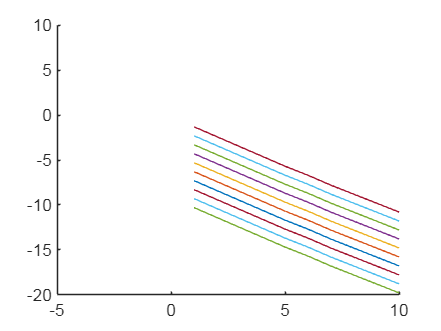

N_L=[1,5,7,11,15];
snr=[40,20,1,-5];
theta=31:40;
phi=-59:-50;
plot(phi-squeeze(res_phi(1,1,:)))

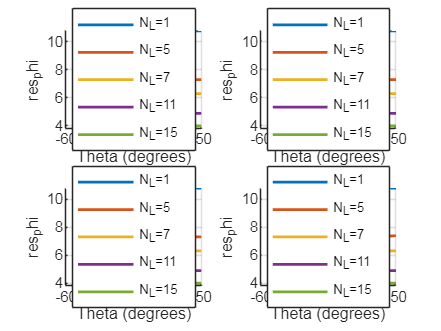


figure;
for s = 1:length(snr)
    subplot(2,2,s); % 创建2x2子图布局
    hold on;
    % s=1;
    % 绘制不同N_L的曲线
    for n = 1:length(N_L)
        plot(phi, squeeze(res_phi(n,s,:))-phi',...
            'LineWidth',1.5,...
            'DisplayName',['N_L=',num2str(N_L(n))]);
    end
    
    title(['SNR = ',num2str(snr(s))]);
    xlabel('PHI (degrees)');
    ylabel('res_phi');
    grid on;
    legend('Location','best');
    hold off;
end

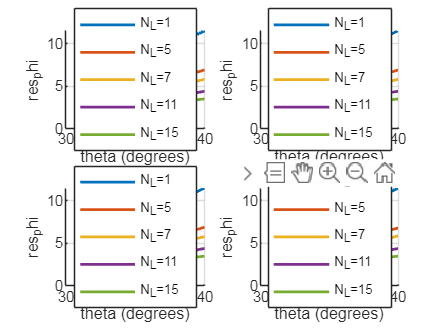

figure;
for s = 1:length(snr)
    subplot(2,2,s); % 创建2x2子图布局
    hold on;
    % s=1;
    % 绘制不同N_L的曲线
    for n = 1:length(N_L)
        plot(theta, squeeze(res_theta(n,s,:))-theta',...
            'LineWidth',1.5,...
            'DisplayName',['N_L=',num2str(N_L(n))]);
    end
    
    title(['SNR = ',num2str(snr(s))]);
    xlabel('theta (degrees)');
    ylabel('res_phi');
    grid on;
    legend('Location','best');
    hold off;
end

squeeze(res_theta(n,:,1))-theta(1)

ans =     5.3000    5.3000    5.3000    5.3000


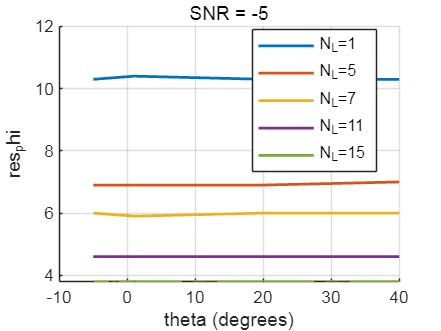

figure;
% for s = 1:length(snr)
    % subplot(2,2,s); % 创建2x2子图布局
    hold on;
    % s=1;
    % 绘制不同N_L的曲线
    for n = 1:length(N_L)
        plot(snr, squeeze(res_phi(n,:,1))-phi(1),...
            'LineWidth',1.5,...
            'DisplayName',['N_L=',num2str(N_L(n))]);
    end
    
    title(['SNR = ',num2str(snr(s))]);
    xlabel('theta (degrees)');
    ylabel('res_phi');
    grid on;
    legend('Location','best');
    hold off;

% end

% param.N_L=1;
% param.snr=40;
% param.theta=30;
% param.phi=0;
% for i=1:5
%     [res_theta(i,j,k),res_phi(i,j,k)]=plane_move_many(param);
% end

ans = 119

最高点坐标: (Theta: 47.00, Phi: 0.00)


ans = 119

最高点坐标: (Theta: 47.00, Phi: 0.00)


ans = 119

最高点坐标: (Theta: 47.00, Phi: 0.00)


ans = 119

最高点坐标: (Theta: 47.00, Phi: 0.00)


ans = 119

最高点坐标: (Theta: 47.00, Phi: 0.00)
